#  Kulite Calibrations

% Load in raw voltage output data before executing 

% Convert Data tables into arrays
% 
KCal1 = table2array(KCal1);
KCal2 = table2array(KCal2);
KCal3 = table2array(KCal3);
KCal4 = table2array(KCal4);
KCal5 = table2array(KCal5);
KCal6 = table2array(KCal6);
KCal7 = table2array(KCal7);

Dcal1 = table2array(Dcal1);
Dcal2 = table2array(Dcal2);
Dcal3 = table2array(Dcal3);
Dcal4 = table2array(Dcal4);
Dcal5 = table2array(Dcal5);
% 
Run1_DT = table2array(Run1_DT);
Run2_DT = table2array(Run2_DT);
Run3_DT = table2array(Run3_DT);
Run4_DT = table2array(Run4_DT);
Run5_DT = table2array(Run5_DT);
% Run6_DT = table2array(Run6_DT);
% Run7_DT = table2array(Run7_DT);
% Run8_DT = table2array(Run8_DT);
% Run9_DT = table2array(Run9_DT);
% Run10_DT = table2array(Run10_DT);
% Run11_DT = table2array(Run11_DT);
% Run12_DT = table2array(Run12_DT);

Run1_K = table2array(Run1_K);
Run2_K = table2array(Run2_K);
Run3_K = table2array(Run3_K);
Run4_K = table2array(Run4_K);
Run5_K = table2array(Run5_K);
% Run6_K = table2array(Run6_K);
% Run7_K = table2array(Run7_K);
% Run8_K = table2array(Run8_K);
% Run9_K = table2array(Run9_K);
% Run10_K = table2array(Run10_K);
% Run11_K = table2array(Run11_K);
% Run12_K = table2array(Run12_K);



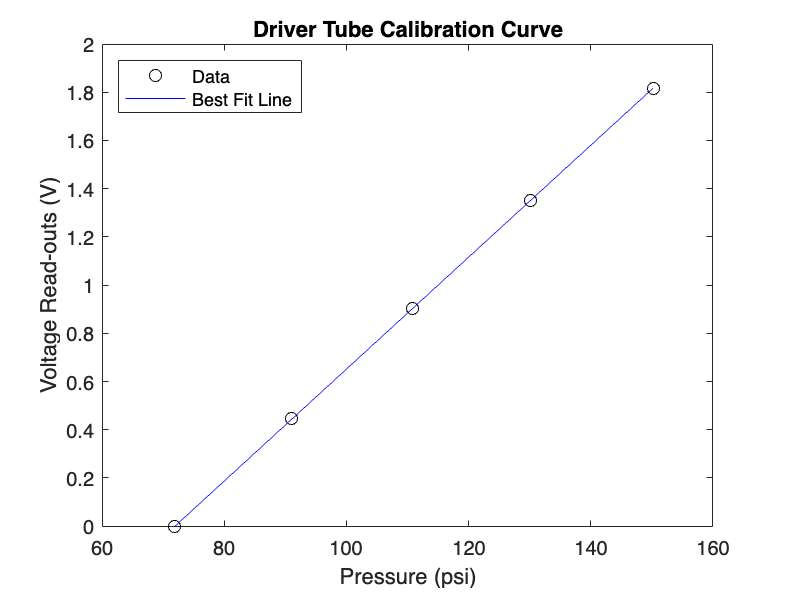

% Plot Driver tube and Kulite calibration curves

% Dcal data
Dcal_points = [sum(Dcal1)./(height(Dcal1)), sum(Dcal2)./(height(Dcal2)), sum(Dcal3)./(height(Dcal3)), sum(Dcal4)./(height(Dcal4)), sum(Dcal5)./(height(Dcal5))];
Dcal_pressures = [71.9 91.0 110.8 130.1 150.2];

% Calibration Curve
Dcal_fit_coeffs = polyfit(Dcal_pressures, Dcal_points, 1);
Dcal_fit = polyval(Dcal_fit_coeffs, Dcal_pressures);

% Plot Dcal data and best-fit line
figure;
plot(Dcal_pressures, Dcal_points, 'ko', 'DisplayName', 'Data');
hold on
plot(Dcal_pressures, Dcal_fit, 'b-', 'DisplayName', 'Best Fit Line');
hold off
legend('Location', 'northwest')
xlabel('Pressure (psi)');
ylabel('Voltage Read-outs (V)');
title('Driver Tube Calibration Curve');

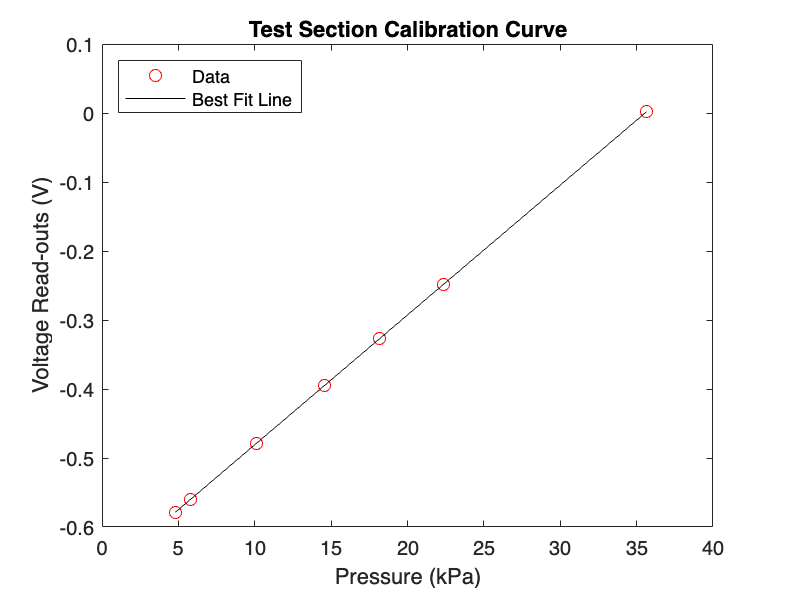


% For KCal data
KCal_points = [sum(KCal1)./(height(KCal1)), sum(KCal2)./(height(KCal2)), sum(KCal3)./(height(KCal3)), sum(KCal4)./(height(KCal4)), sum(KCal5)./(height(KCal5)), sum(KCal6)./(height(KCal6)), sum(KCal7)./(height(KCal7))];
KCal_pressures = [35.65 22.38 18.18 14.55 10.09 5.80 4.80];

% Find best-fit line for KCal data
KCal_fit_coeffs = polyfit(KCal_pressures, KCal_points, 1);
KCal_fit = polyval(KCal_fit_coeffs, KCal_pressures);

% Plot KCal data and best-fit line
figure;
plot(KCal_pressures, KCal_points, 'ro', 'DisplayName', 'Data');
hold on
plot(KCal_pressures, KCal_fit, 'k-', 'DisplayName', 'Best Fit Line');
hold off
legend('Location', 'northwest')
xlabel('Pressure (kPa)');
ylabel('Voltage Read-outs (V)');
title('Test Section Calibration Curve');

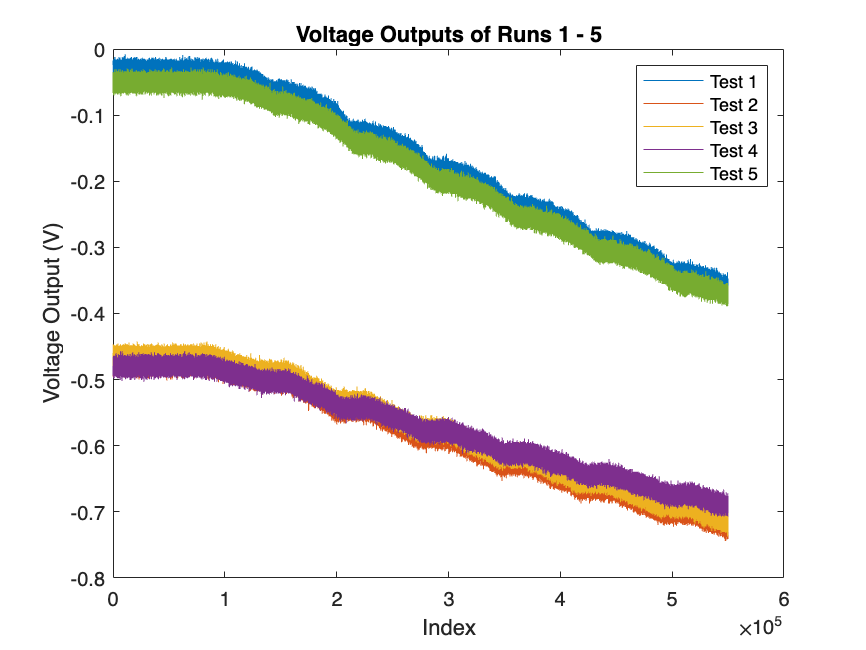

% Plots of Test Run Driver Tube Pressures

plot(Run1_DT, 'DisplayName', 'Test 1');
hold on;
plot(Run2_DT, 'DisplayName', 'Test 2');
plot(Run3_DT, 'DisplayName', 'Test 3');
plot(Run4_DT, 'DisplayName', 'Test 4');
plot(Run5_DT, 'DisplayName', 'Test 5');
% plot(Run6_DT, 'DisplayName', 'Test 6');
% plot(Run7_DT, 'DisplayName', 'Test 7');
% plot(Run8_DT, 'DisplayName', 'Test 8');
% plot(Run9_DT, 'DisplayName', 'Test 9');
% plot(Run10_DT, 'DisplayName', 'Test 10');
% plot(Run11_DT, 'DisplayName', 'Test 11');
% plot(Run12_DT, 'DisplayName', 'Test 12');
% plot(Run13_DT, 'DisplayName', 'Test 13');
% plot(Run14_DT, 'DisplayName', 'Test 14');
% plot(Run15_DT, 'DisplayName', 'Test 15');
% plot(Run16_DT, 'DisplayName', 'Test 16');
% plot(Run17_DT, 'DisplayName', 'Test 17');

% Adding labels and legend
title('Voltage Outputs of Runs 1 - 5');
xlabel('Sample Duration');
ylabel('Voltage Output (V)');
%legend('show');

hold off;

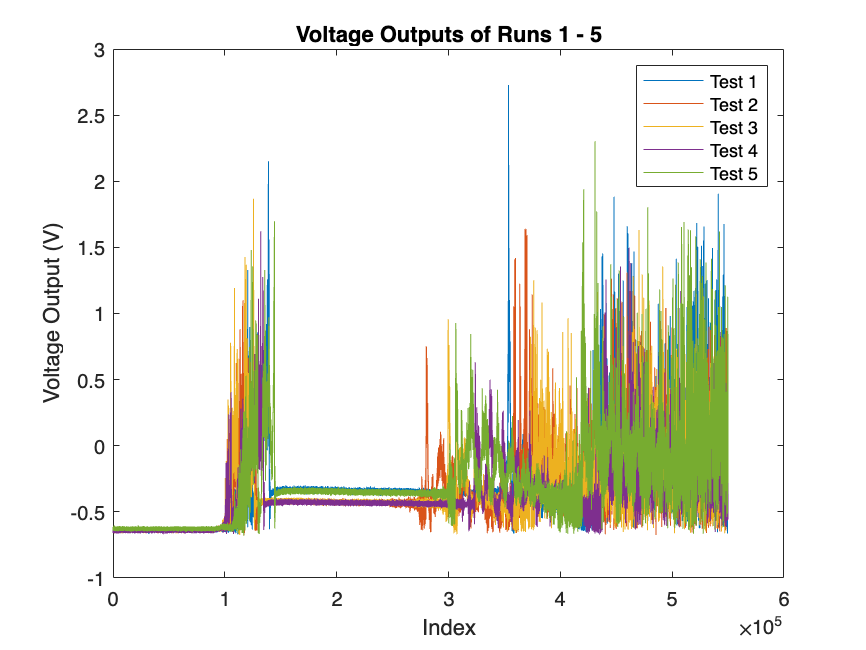

% Plots of Test Run Kulite Pressures

figure;

plot(Run1_K, 'DisplayName', 'Test 1');
hold on;
plot(Run2_K, 'DisplayName', 'Test 2');
plot(Run3_K, 'DisplayName', 'Test 3');
plot(Run4_K, 'DisplayName', 'Test 4');
plot(Run5_K, 'DisplayName', 'Test 5');
% plot(Run6_K, 'DisplayName', 'Test 6');
% plot(Run7_K, 'DisplayName', 'Test 7');
% plot(Run8_K, 'DisplayName', 'Test 8');
% plot(Run9_K, 'DisplayName', 'Test 9');
% plot(Run10_K, 'DisplayName', 'Test 10');
% plot(Run11_K, 'DisplayName', 'Test 11');
% plot(Run12_K, 'DisplayName', 'Test 12');
% plot(Run13_K, 'DisplayName', 'Test 13');
% plot(Run14_K, 'DisplayName', 'Test 14');
% plot(Run15_K, 'DisplayName', 'Test 15');
% plot(Run16_K, 'DisplayName', 'Test 16');
% plot(Run17_K, 'DisplayName', 'Test 17');

% Adding labels and legend
title('Campaign #1 Voltage Outputs');
xlabel('Sample Duration');
ylabel('Voltage Output (V)');
%legend('show');

hold off;